## Part 2 : Processing Sleep Patterns of New Babies

New born baby sleep cycle :

load EEG/data.mat

### Assigning index to each sleep stage

The REM sleep stage is frequently called “active sleep” and NREM is called “quiet sleep.” During “active sleep,” or REM, a baby can be seen making small movements. The baby’s eyes move around (while closed), their limbs and fingers might twitch or jerk, their breathing might speed up, and they might move their mouths. During “quiet sleep,” or NREM, the baby is still and does not make these movements.([Source](https://www.sleepfoundation.org/baby-sleep/baby-sleep-cycle))

-  qt - Quiet sleep, trace alternant(NERM) 

- qh - Quiet sleep, high voltage(NREM)

- tr - Transitional sleep

- al - Active sleep, low voltag(REM)

- ah - Active sleep, high voltage(REM)

- aw - Awake

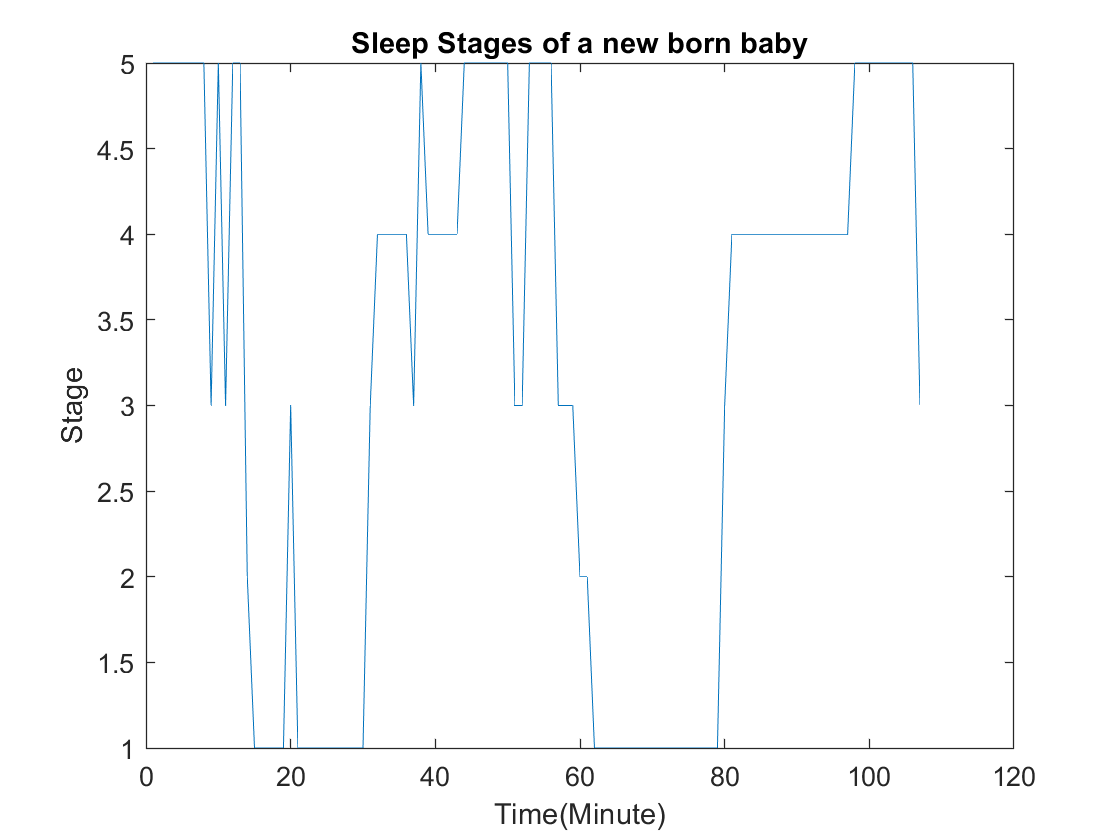

len = length(data);
data2 = zeros(1,len);
for i = 1:len
    if data(i) == "qt"
        data2(i) = 1;
    elseif data(i) == "qh"
        data2(i) = 2;
    elseif data(i) == "tr"
        data2(i) = 3;
    elseif data(i) == "al"
        data2(i) = 4;
    elseif data(i) == "ah"
        data2(i) = 5;
    elseif data(i) == "aw"
        data2(i) = 6;
    end
end

plot(data2);
title("Sleep Stages of a new born baby");
ylabel("Stage");
xlabel("Time(Minute)");

Newborn babies spend roughly 50% of their time asleep in REM. In the diagram above, roughly 50% od new born baby is in REM stage.

## Fourier Transform of Sleep Stages

fft_sleep_stages = fft(data2);

## Graph of Fourier Transform

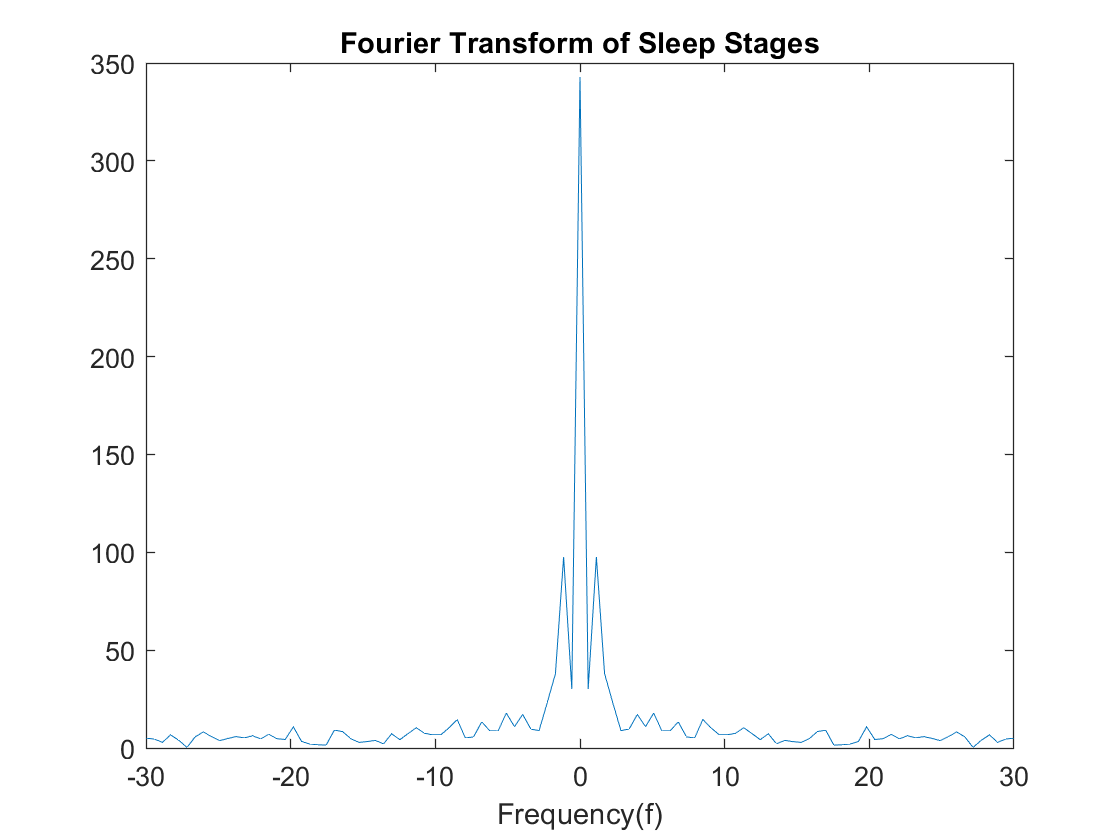

fs = 60;
% Frequency Vector
f = linspace(-fs/2,fs/2,numel(data2));
fft_sleep_stages_shift = fftshift(fft_sleep_stages);
plot(f,abs(fft_sleep_stages_shift));
title("Fourier Transform of Sleep Stages");
xlabel("Frequency(f)");

### **Question : How many times baby’s sleep cycle is completed during an hour?**

The baby’s sleep cycle is completed only 1 time during an hour.

### **Question : **If we change order of indexes, is it still analysable?

If the consecutive sleep stages have different indexes, then this is not **analysable**. 

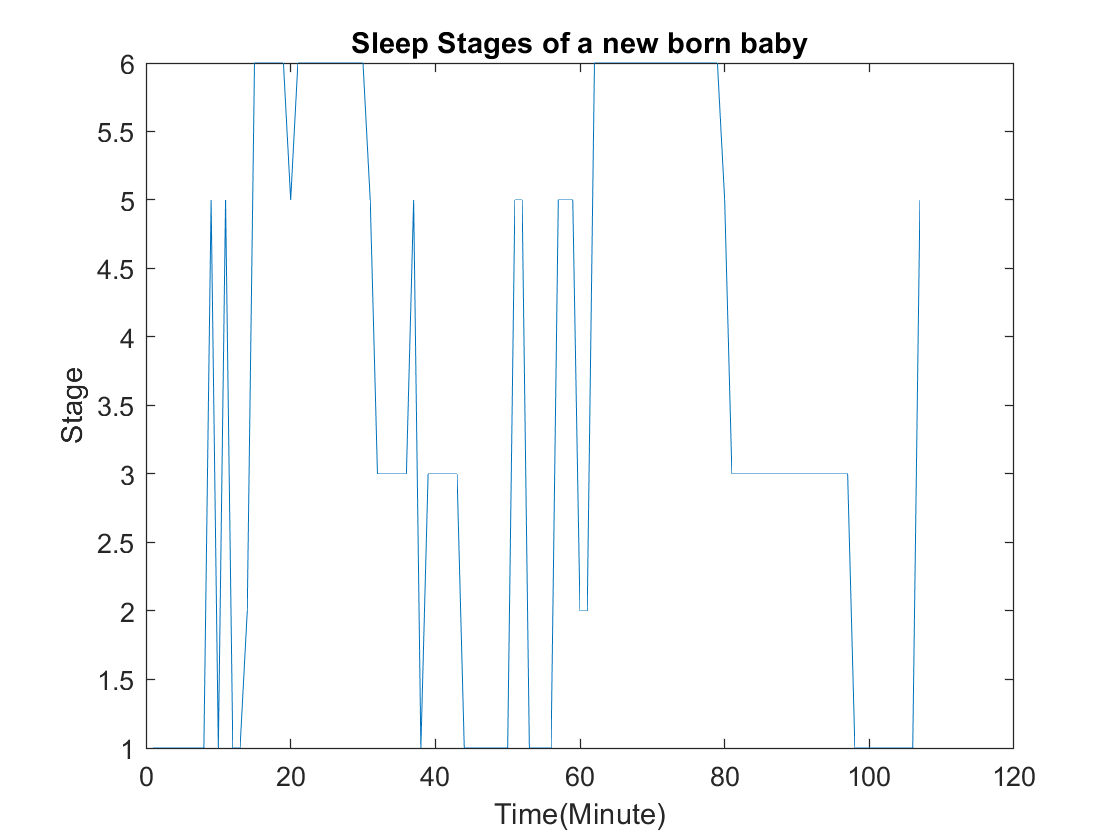

len = length(data);
data3 = zeros(1,len);
for i = 1:len
    if data(i) == "qt"
        data3(i) = 6;
    elseif data(i) == "qh"
        data3(i) = 2;
    elseif data(i) == "tr"
        data3(i) = 5;
    elseif data(i) == "al"
        data3(i) = 3;
    elseif data(i) == "ah"
        data3(i) = 1;
    elseif data(i) == "aw"
        data3(i) = 4;
    end
end

plot(data3);
title("Sleep Stages of a new born baby");
ylabel("Stage");
xlabel("Time(Minute)");

As you can see the diagram is kind of random.

## Assigning different indexes to sleep stages

order of indexes : 1 1 2 2 3 3 -> qt qh tr al ah aw

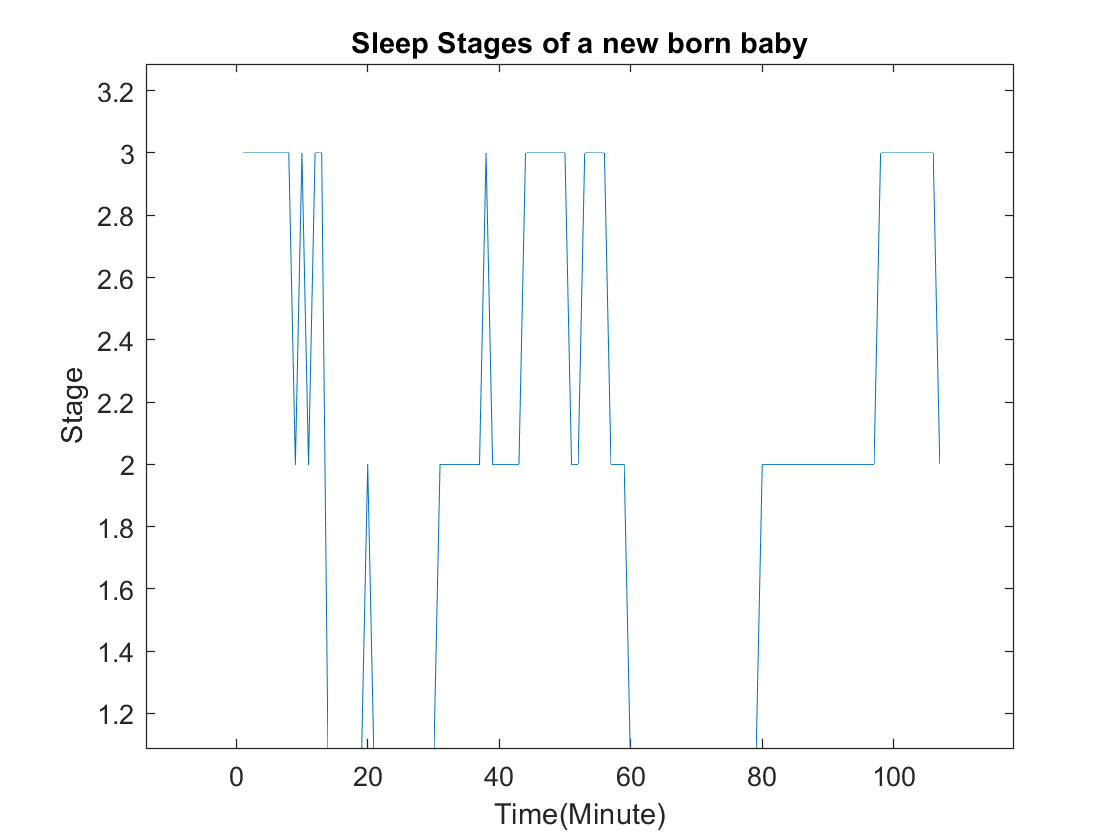

for i = 1:len
    if data(i) == "qt" || data(i) == "qh"
        data2(i) = 1;
    elseif data(i) == "tr" || data(i) == "al"
        data2(i) = 2;
    elseif data(i) == "ah" || data(i) == "aw"
        data2(i) = 3;
    end
end

plot(data2);
title("Sleep Stages of a new born baby");
ylabel("Stage");
xlabel("Time(Minute)");

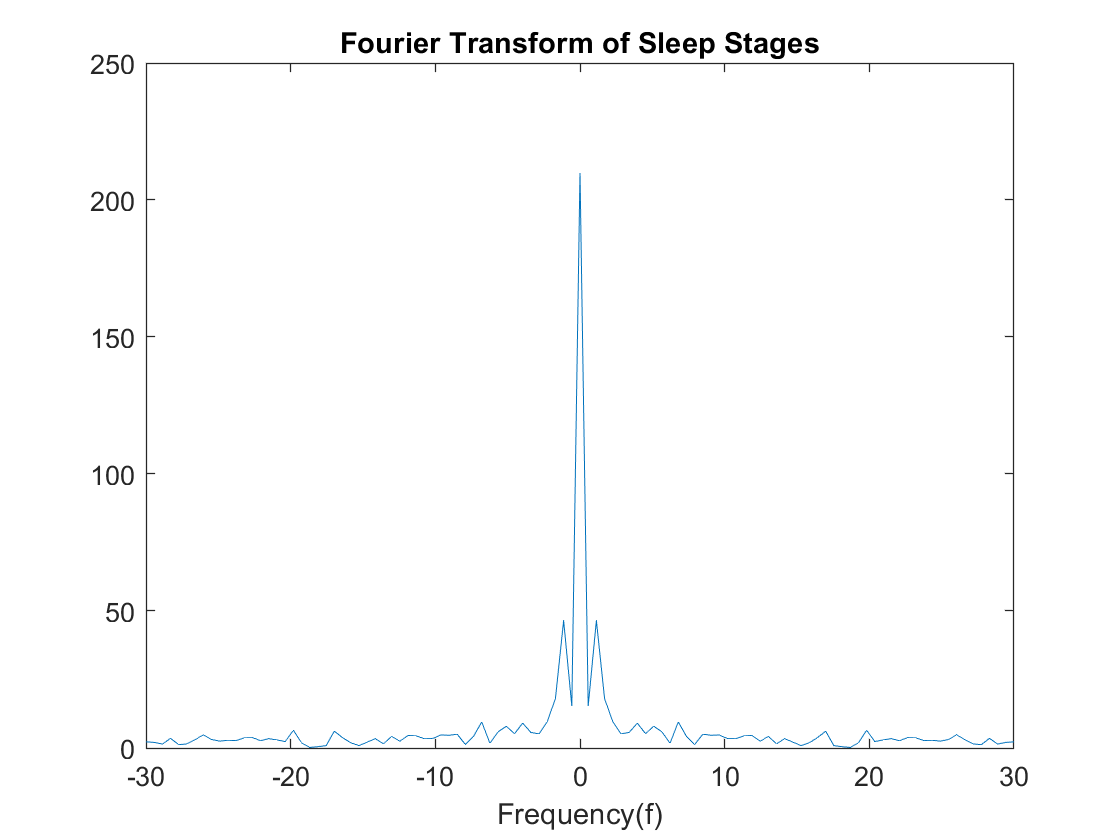

fft_sleep_stages = fft(data2);
% Frequency Vector
fft_sleep_stages_shift = fftshift(fft_sleep_stages);
plot(f,abs(fft_sleep_stages_shift));
title("Fourier Transform of Sleep Stages");
xlabel("Frequency(f)");

As you can see the results are **similar**.

### Question : Why changing the indexes didn't affect the results?

Because the order of consecutive sleep didn't change. If we assign random indexes to each sleep stage, the result will not be analysable.